# **HW6 Program Assignment**

**TA: 陳永泰 **

## P1 (10%)

    Consider again the inverse DFT given in (8.2). 

            $X\left\lbrack n\right\rbrack =\frac{1}{N}\sum_{k=0}^{N-1} X\left\lbrack k\right\rbrack W_N^{-\textrm{kn}}$,    n = 0,1,2,...,N-1           (8.2)

    (a) (5%)Replace k by ${\left\langle -k\right\rangle }_N$ in (8.2) and show that the resulting summation is a DFT expression, that is, $\mathrm{I}\mathrm{D}\mathrm{F}\mathrm{T}{\left\{X{\left[k\right]}\right\}}=\frac{1}{N}\textrm{DFT}{\left\{X{\left[{{\left〈-k\right〉}}_N \right]}\right\}}$

        ans:

            
$$\begin{array}{l}
x\left\lbrack n\right\rbrack =\frac{1}{N}\sum_{k=0}^{N-1} X\left\lbrack {\left\langle -k\right\rangle }_N \right\rbrack W_N^{-n{\left\langle -k\right\rangle }_N } \\
\;\;\;\;\;\;\;\;=\frac{1}{N}\sum_{k=0}^{N-1} X\left\lbrack {\left\langle -k\right\rangle }_N \right\rbrack W_N^{-n\left(N-k\right)} =\frac{1}{N}\sum_{k=0}^{N-1} X\left\lbrack {\left\langle -k\right\rangle }_N \right\rbrack W_N^{-\textrm{nk}} \\
\;\;\;\;\;\;\;\;=\textrm{DFT}\left\lbrace X\left\lbrack {\left\langle -k\right\rangle }_N \right\rbrack \right\rbrace 
\end{array}$$


    (b) (5%)Develop a MATLAB function** x = IDFT(X,N)** using the fft function that uses the above approach. Verify your function on signal x[n] = {1, 2, 3, 4, 5, 6, 7, 8}.

% see function IDFT() at the end of the script
close all; clc; clear all
xn = 1:8;
X = fft(xn);
xr = IDFT(X,length(xn))

xr =      1     2     3     4     5     6     7     8


## P2 (15%)

    In this problem we will investigate differences in the speeds of DFT and FFT algorithms when stored twiddle factors are used.

    (a) Write a function **W = dft_matrix(N)** that computes the DFT matrix $W_N$ given in (8.8).

% see function DFTmtx()
n = 8;
D = dft_matrix(n)

D =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.7071 - 0.7071i   0.0000 - 1.0000i  -0.7071 - 0.7071i  -1.0000 - 0.0000i  -0.7071 + 0.7071i  -0.0000 + 1.0000i   0.7071 + 0.7071i
   1.0000 + 0.0000i   0.0000 - 1.0000i  -1.0000 - 0.0000i  -0.0000 + 1.0000i   1.0000 + 0.0000i   0.0000 - 1.0000i  -1.0000 - 0.0000i  -0.0000 + 1.0000i
   1.0000 + 0.0000i  -0.7071 - 0.7071i  -0.0000 + 1.0000i   0.7071 - 0.7071i  -1.0000 - 0.0000i   0.7071 + 0.7071i   0.0000 - 1.0000i  -0.7071 + 0.7071i
   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i
   1.0000 + 0.0000i  -0.7071 + 0.7071i   0.0000 - 1.0000i   0.7071 + 0.7071i  -1.0000 - 0.0000i   0.7071 - 0.7071i  -0.0000 + 1.0000i  -0.7071 - 0.7071i
   1.0000 + 0.0000i  -0.0000 + 1.0000i  -1.0000 - 0.0000i   0.0000 - 1.0000i  

    (b) (5%)Write a function **X = dftdirect_m(x,W)** that modifies the **dftdirect** function using the matrix W from (a). Using the **tic** and **toc** functions compare computation times for the **dftdirect** and **dftdirect_m** function for N = 128, 256, 512, and 1024. For this purpose generate an N-point complex-valued signal as **x = randn(1,N) + 1j*randn(1,N).**

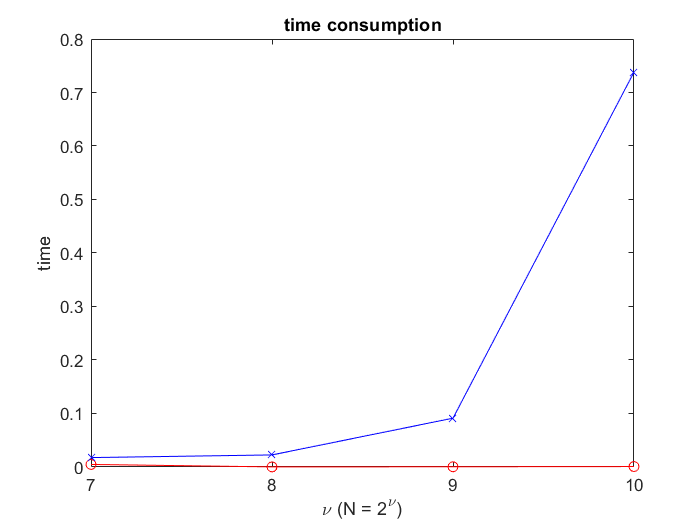

% see function dftdirect_m(x,W) at the end of the script
time_dir = [];
time_m = [];
n = [128 256 512 1024];
nu = log2(n);
for N = n
    x = randn(1,N) + 1j*randn(1,N);
    tic;  
    X = dftdirect(x);
    time_dir = cat(1,time_dir,toc);
end

for N = n
    x = randn(1,N) + 1j*randn(1,N);
    W = dft_matrix(N);
    tic;
    X = dftdirect_m(x,W);
    time_m = cat(1,time_m,toc);
end

% plot
figure
plot(nu,time_m,'o-','color','red');hold on;
plot(nu,time_dir,'x-','color','blue')
title('time consumption')
xlabel('\nu (N = 2^{\nu})')
ylabel('time')
set(gca, 'XTick', nu)    

    (c) (5%)Write a function **X = fftrecur_m(x,W)** that modifies the **fftrecur** function given on page 439 using the matrix W from (a). Using the **tic** and **toc** functions compare computation times for the **fftrecur** and **fftrecur_m** function for N = 128, 256, 512, and 1024. For this purpose generate an N-point complex valued signal as** x = randn(1,N) + 1j*randn(1,N)**.

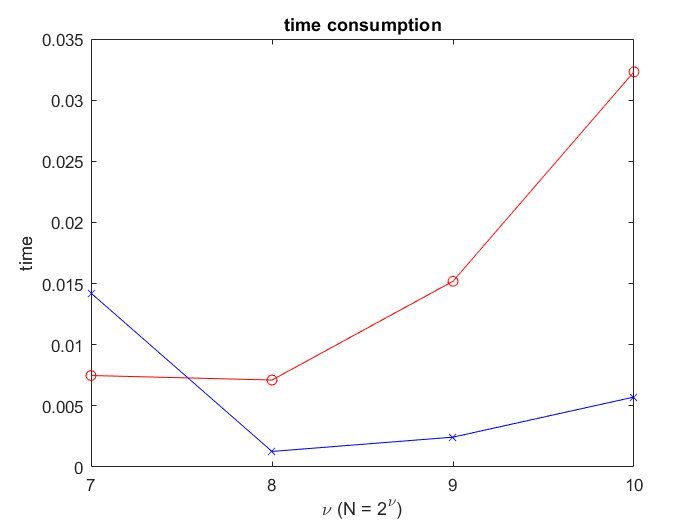

% see function fftrecur_m(x,W) at the end of the script
time_m = [];
time_dir = [];
n = [128 256 512 1024];
nu = log2(n);
for N = n
    x = randn(1,N) + 1j*randn(1,N);
    W = dft_matrix(N);
    tic;
    X = fftrecur(x);
    time_dir = cat(1,time_dir,toc);
end
for N = n
    x = randn(1,N) + 1j*randn(1,N);
    W = dft_matrix(N);
    tic;
    X = fftrecur_m(x,W);
    time_m = cat(1,time_m,toc);
end

% plot
figure
plot(nu,time_m,'o-','color','red');hold on;
plot(nu,time_dir,'x-','color','blue')
title('time consumption')
xlabel('\nu (N = 2^{\nu})')
ylabel('time')
set(gca, 'XTick', nu)     

## P3 (15%)

    Consider the flow graph in **Figure 8.10** which implements a DIT-FFT algorithm with both input and output in natural order. Let the nodes at each stage be labeled as s­­­m[k], 0 ≤m ≤ 3 with s0[k] = x[k] and s3[k] = X[k], 0 ≤ k ≤ 7.

    (a) (5%)Express sm[k] in terms of sm-1[k] for m = 1, 2, 3.

        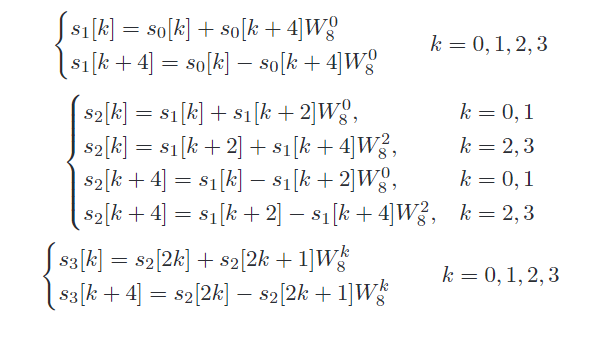

    (b) (5%)Write a MATLAB function **X = fftalt8(x) **that computes an 8-point DFT using the equations in part (a). Verify with sequence x[n] = {0,1,2,2,3,3,3,4}.

% see function fftalt8(x) at the end of the script
x = [0 1 2 2 3 3 3 4];
fft(x)

ans =   18.0000 + 0.0000i  -3.0000 + 3.8284i  -2.0000 + 2.0000i  -3.0000 + 1.8284i  -2.0000 + 0.0000i  -3.0000 - 1.8284i  -2.0000 - 2.0000i  -3.0000 - 3.8284i


X = fftalt8(x)

X =   18.0000 + 0.0000i  -3.0000 + 3.8284i  -2.0000 + 2.0000i  -3.0000 + 1.8284i  -2.0000 + 0.0000i  -3.0000 - 1.8284i  -2.0000 - 2.0000i  -3.0000 - 3.8284i


    (c) (5%)Compare the coding complexity of the above function with that of MATLAB function fftditr2 shown in **Figure 8.6**, and comment on its usefulness.

        ans: The coding complexity of the above function is much larger than that of the `fftditr2 `function since the equations are not recursive.

## P4 (10%)

Using the flow graph of Figure 8.13 and following the approach used in developing the fftditr2 function.

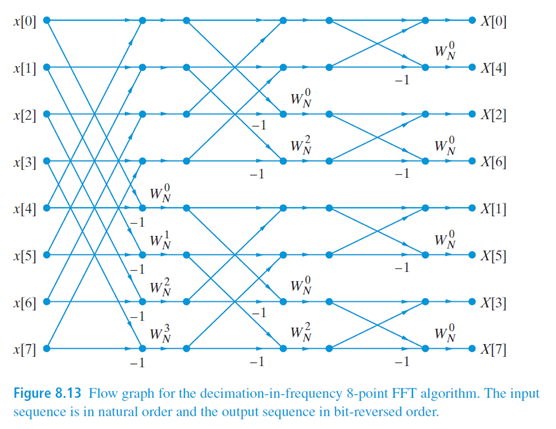

    (a) (5%)Develop a radix-2 DIF-FFT function X = fftdifr2(x) for power-of-2 length N.

% see function fftdifr2(x) at the end of the script

    (b) (5%)Verify your function for N = 2^ν where 2 ≤ ν ≤ 10. For this purpose generate an N-point complex-valued signal as **x = randn(1,N) + 1j*randn(1,N).**

for v = 2:10
    N = 2^v;
    x = randn(1,N) + 1j*randn(1,N);
    X_fft = fft(x);
    X_fftdit = fftdifr2(x);
    diff = abs(X_fft-X_fftdit)>10^-7;
    if(sum(diff)>0)
        display(['error when v= ',num2str(v)]);
    else 
        display(['pass for v= ',num2str(v)]); 
    end
end

pass for v= 2
pass for v= 3
pass for v= 4
pass for v= 5
pass for v= 6
pass for v= 7
pass for v= 8
pass for v= 9
pass for v= 10


## P5(10%)

The **filterfirdf** implements the FIR direct form structure.

    (a) (5%)Develop a new MATLAB function **y=filterfirlp(h,x) **that implements the FIR linear-phase form given its impulse response in **h**. This function should first check if **h** is one of type-I through type-IV and then simulate the corresponding equations. If** h** does not correspond to one of the four types then the function should display an appropriate error message.

% see function filterfirlp(h,x) below

    (b) (5%)Verify your function on each of the following FIR systems:

h1[n] = {1,2,3,2,1},

             ↑

h2[n] = {1,-2,3,3,-2,1},

             ↑

h3[n] = {1,-5,0,5,-1},

             ↑

h4[n] = {1,-3,-4,4,3,-1},

             ↑

h5[n] = {1,2,3,-2,-1},

             ↑

close all; clc
n = 0:9;
xn = ones(size(n));
%% h1:
h = [1 2 3 2 1];
y = filterfirlp(h,xn);
y_ref = filter(h,1,xn);
max(abs(y-y_ref))

ans = 0

%% h2:
h = [1 -2 3 3 -2 1];
y = filterfirlp(h,xn);
y_ref = filter(h,1,xn);
max(abs(y-y_ref))

ans = 0

%% h3:
h = [1 -5 0 5 -1];
y = filterfirlp(h,xn);
y_ref = filter(h,1,xn);
max(abs(y-y_ref))

ans = 0

%% h4:
h = [1 -3 -4 4 3 -1];
y = filterfirlp(h,xn);
y_ref = filter(h,1,xn);
max(abs(y-y_ref))

ans = 0

%% h5:
h = [1 2 3 -2 -1];
y = filterfirlp(h,xn);

Error using HW6_ans>filterfirlp (line 216)
Impulse Response is not symmetric

## P6 (10%)

Consider the IIR normal direct form II structure given in **Figure 9.6** and implemented by (9.18)and (9.20). 

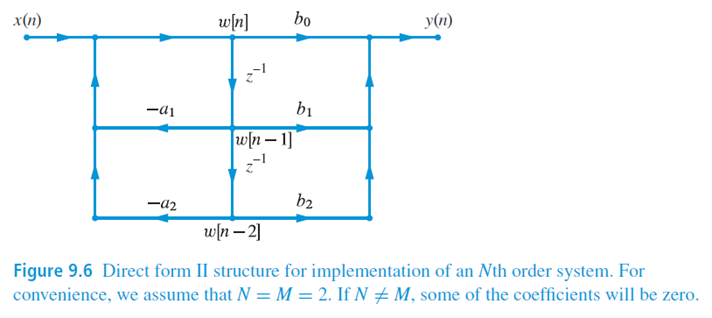

    (a) (5%)Using the MATLAB function **filterdf1** as a guide, develop a MATLAB function **y=filterdf2(b,a,x)** that implements the normal direct form II structure. Assume zero initial conditions.

% see function filterdf2(b,a,x) below

    (b) (5%)Determine y[n], 0 ≤ n ≤ 500 using your function and filterdf1 function with following inputs:

    
$$\mathrm{x}{\left[n\right]}={\left(\frac{1}{4}\right)}^n u{\left[n\right]},\ a={\left[\begin{array}{ccc}
1 & -\frac{3}{2} & \frac{1}{2}
\end{array}\right]},\ b=1$$


         Compare your results to verify that your filterdf2function is correctly implemented.

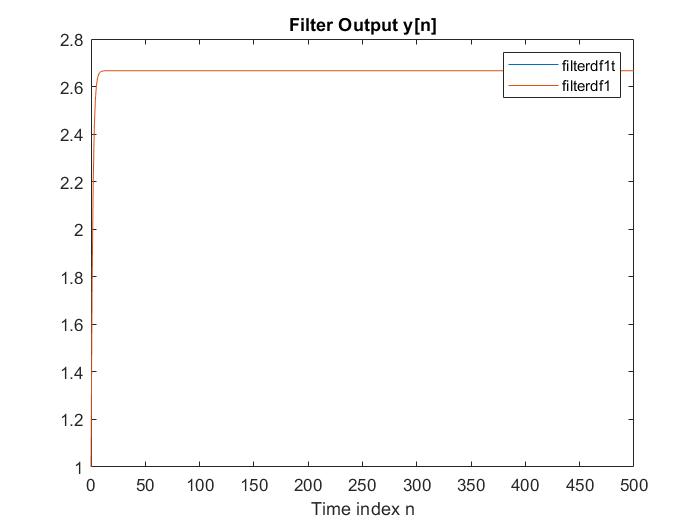

b = 1;
a = [1 -3/2 1/2];
n = 0:500;
%% Numerical Result 1:
xn = (1/4).^n;
yn = filterdf2(b,a,xn);
yn_ref = filterdf1(b,a,xn);
%% plot:    
plot(n,yn,n,yn_ref)
xlabel('Time index n')
title('Filter Output y[n]')
legend('filterdf1t','filterdf1','location','northeast')

## P7(20%)

The following numerator and denominator arrays in MATLAB represent the system function of a discrete-time system in direct form:

    b = [1,-2.61,2.75,-1.36,0.27], a = [1,-1.05,0.91,-0.8,0.38].

Determine and draw each of the following structures:

b = [1,-2.61,2.75,-1.36,0.27];
a = [1,-1.05,0.91,-0.8,0.38];
tf2sos(b,a)

(a) (5%)Cascade form with second-order sections in normal direct form I,

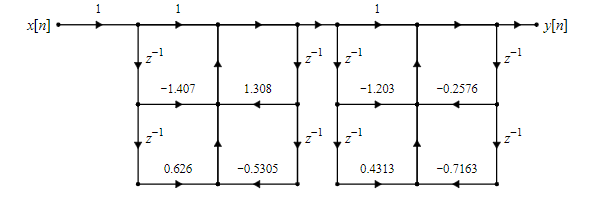

(b) (5%)Cascade form with second-order sections in transposed direct form I,

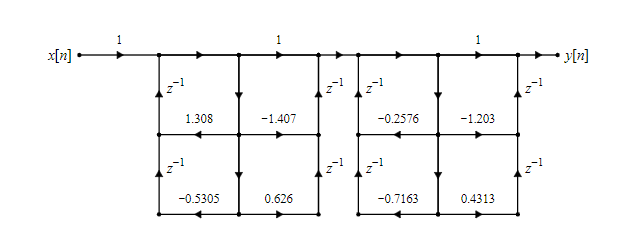

(c) (5%)Cascade form with second-order sections in normal direct form II,

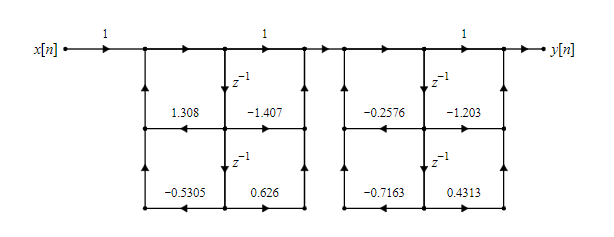

(d) (5%)Cascade form with second-order sections in transposed direct form II

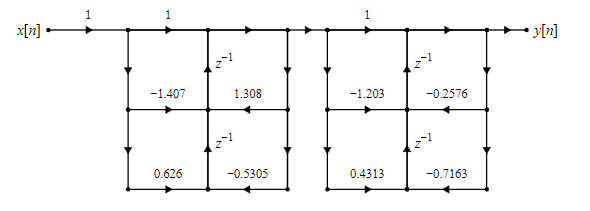

## P8 (10%)

The frequency-sampling form is developed using (9.50) which uses complex arithmetic.

    (a) (5%) Develop a MATLAB function **[G,sos]=firdf2fs(h) **that determines frequency sampling form parameters given in (9.51) and (9.52) given the impulse response in **h**. The matrix **sos** should contain second-order section coefficients in the form similar to the **tf2sos** function while **G** array should contain the respective gains of second-order sections. Incorporate the coefficients for the H[0] and H[N/2] terms in **sos** and **G** arrays.

% see function firdf2fs(h) below

    (b) (2%)Verify your function by input h with sampled frequency response (9.53) and compare with the system function (9.54)

   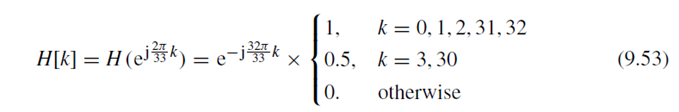

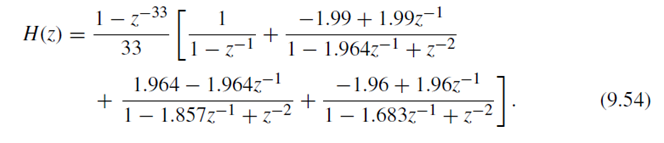

N = 33;
alpha = (N-1)/2; 
k = 0:N-1;
magHk = [1,1,1,0.5,zeros(1,26),0.5,1,1];
angHk = -32*pi*k/33;
H = magHk.*exp(1j*angHk);
h = real(ifft(H,N));
[G,sos] = firdf2fs(h)

H =    1.0000 + 0.0000i  -0.9955 - 0.0951i   0.9819 + 0.1893i  -0.4797 - 0.1409i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.4797 + 0.1409i   0.9819 - 0.1893i  -0.9955 + 0.0951i


G =     1.0000
         0
    2.0000
    2.0000
    1.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


sos =     1.0000         0         0    1.0000   -1.0000         0
    1.0000         0         0    1.0000    1.0000         0
   -0.9955    0.9955         0    1.0000   -1.9639    1.0000
    0.9819   -0.9819         0    1.0000   -1.8567    1.0000
   -0.9595    0.9595         0    1.0000   -1.6825    1.0000
    0.4253    0.3168         0    1.0000   -1.4475    1.0000
    0.0962   -0.8666         0    1.0000   -1.1601    1.0000
   -0.1176    0.9522         0    1.0000   -0.8308    1.0000
   -0.5758    0.9303         0    1.0000   -0.4715    1.0000
   -0.9391   -0.2987         0    1.0000   -0.0952    1.0000



[[G G G].*sos(:,1:3) sos(:,4:end)]

ans =     1.0000         0         0    1.0000   -1.0000         0
         0         0         0    1.0000    1.0000         0
   -1.9909    1.9909         0    1.0000   -1.9639    1.0000
    1.9639   -1.9639         0    1.0000   -1.8567    1.0000
   -0.9595    0.9595         0    1.0000   -1.6825    1.0000
    0.0000    0.0000         0    1.0000   -1.4475    1.0000
    0.0000   -0.0000         0    1.0000   -1.1601    1.0000
   -0.0000    0.0000         0    1.0000   -0.8308    1.0000
   -0.0000    0.0000         0    1.0000   -0.4715    1.0000
   -0.0000   -0.0000         0    1.0000   -0.0952    1.0000



clear
H=zeros(1,33);
H(1)=exp(-j*32*pi/33*0);
H(2)=exp(-j*32*pi/33*1);
H(3)=exp(-j*32*pi/33*2);
H(32)=exp(-j*32*pi/33*31);
H(33)=exp(-j*32*pi/33*32);
H(4)=exp(-j*32*pi/33*3)*0.5;
H(31)=exp(-j*32*pi/33*30)*0.5;
ifft(H)

ans =    0.0004 - 0.0000i   0.0033 - 0.0000i   0.0073 - 0.0000i   0.0095 - 0.0000i   0.0075 - 0.0000i   0.0000 - 0.0000i  -0.0117 - 0.0000i  -0.0239 - 0.0000i  -0.0315 - 0.0000i  -0.0291 - 0.0000i  -0.0133 - 0.0000i   0.0166 - 0.0000i   0.0572 + 0.0000i   0.1022 + 0.0000i   0.1430 + 0.0000i   0.1716 + 0.0000i   0.1818 + 0.0000i   0.1716 + 0.0000i   0.1430 + 0.0000i   0.1022 + 0.0000i   0.0572 + 0.0000i   0.0166 - 0.0000i  -0.0133 - 0.0000i  -0.0291 - 0.0000i  -0.0315 - 0.0000i  -0.0239 - 0.0000i  -0.0117 - 0.0000i  -0.0000 - 0.0000i   0.0075 - 0.0000i   0.0095 - 0.0000i   0.0073 - 0.0000i   0.0033 - 0.0000i   0.0004 - 0.0000i


fft(ifft(H))

ans =    1.0000 + 0.0000i  -0.9955 - 0.0951i   0.9819 + 0.1893i  -0.4797 - 0.1409i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.4797 + 0.1409i   0.9819 - 0.1893i  -0.9955 + 0.0951i


Functions

function x = IDFT(X,N)
    X = [X(1) X(end:-1:2)];
    x = fft(X)/N;
end

function D = dft_matrix(n)    
    f = 2*pi/n;            % Angular increment.
    w = (0:f:2*pi-f/2).' * 1i;  % Column.
    x = 0:n-1;             % Row.
    D = exp(-w*x);              % Exponentiation of outer product.
end

function X = dftdirect_m(x,W)
    X = x*W;
end

function Xdft = fftrecur_m(x,W)
    N = length(x);
    if N ==1
        Xdft = x;
    else
        m = N/2;
        W_2 = W(1:2:N,1:m);
        XE = fftrecur_m(x(1:2:N),W_2);
        XO = fftrecur_m(x(2:2:N),W_2);
        temp = W(1:m,2).*XO;
        Xdft = [ XE+temp ; XE-temp ];
    end
end

function X = fftalt8(x)
    N = 8;
    s = x;
    w = exp(-j*2*pi/N).^(0:N-1);
    % Stage I:
    temp = s;
    s(1:4) = temp(1:4)+temp(5:8);
    s(5:8) = temp(1:4)-temp(5:8);
    temp = s;
    s(1:2) = temp(1:2)+temp(3:4);
    s(3:4) = temp(5:6)+temp(7:8)*w(3);
    s(5:6) = temp(1:2)-temp(3:4);
    s(7:8) = temp(5:6)-temp(7:8)*w(3);
    % Stage III:
    temp = s;
    s(1:4) = temp(1:2:end)+temp(2:2:end).*w(1:4);   
    s(5:8) = temp(1:2:end)-temp(2:2:end).*w(1:4);
    X = s;
end

function x=fftdifr2(x)
    N=length(x); nu=log2(N);
    for m=nu:-1:1;
        L=2^m;
        L2=L/2;
        for ir=1:L2;
            W=exp(-1i*2*pi*(ir-1)/L);
            for it=ir:L:N;
                ib=it+L2;
                temp=x(it)+x(ib);
                x(ib)=x(it)-x(ib);
                x(ib)=x(ib)*W;
                x(it)=temp;
            end
        end
    end
    x = bitrevorder(x);
end

function y = filterfirlp(h,x)
    nh = length(h);
    M = nh-1;
    nx = length(x);
    x = [zeros(1,M) x(:)'];
    y = zeros(1,nx);
    eo = mod(M,2) ~= 0;
    if max(abs(h + fliplr(h))) == 0
        syasy = 1;
    elseif max(abs(h - fliplr(h))) == 0
        syasy = 0;
    else 
        error('Impulse Response is not symmetric')
    end
    h = h';
    caseind = 2*syasy + eo;
    switch caseind
        case 0
            MM = M/2;
            for n = 1:nx
                y(n) = (x(n+M:-1:n+M-MM+1)+x(n:1:n+MM-1))*h(1:MM)+ h(MM+1)*x(n+M-MM);
            end
        case 1
            MM = (M-1)/2+1;
            for n = 1:nx
                y(n) = (x(n+M:-1:n+M-MM+1)+x(n:1:n+MM-1))*h(1:MM);
            end
        case 2
            MM = M/2;
            for n = 1:nx
                y(n) = (x(n+M:-1:n+M-MM+1)-x(n:1:n+MM-1))*h(1:MM);
            end
        case 3
            MM = (M-1)/2+1;
            for n = 1:nx
                y(n) = (x(n+M:-1:n+M-MM+1)-x(n:1:n+MM-1))*h(1:MM);
            end
    end
end

function [y] = filterdf2(b,a,x)
    M = length(b)-1; N = length(a)-1; K = max(M,N);
    a0 = a(1); a = reshape(a,1,N+1)/a0;
    b = reshape(b,1,M+1)/a0; a = a(2:end);
    Lx = length(x); x = [zeros(K,1);x(:)];
    Ly = Lx+K; y = zeros(1,Ly); w = zeros(Ly,1);
    for n = K+1:Ly
        w(n) = x(n) - a*w(n-1:-1:n-N);
        y(n) = b*w(n:-1:n-M);
    end
    y = y(K+1:Ly);
end

function [G,sos] = firdf2fs(h)
    N = length(h);
    if mod(N,2) == 0
        K = N/2-1;
    else
        K = (N-1)/2;
    end
    G = zeros(K+2,1);
    H = fft(h);
    Hmag = abs(H);
    Hang = angle(H);
    G(1) = H(1);
    G(3:end) = 2*Hmag(2:1+K);
    sos = zeros(K+2,6);
    sos(1,:) = [1 0 0 1 -1 0];
    sos(2,:) = [1 0 0 1 1 0];
    for ii = 1:K
        sos(2+ii,:) = [cos(Hang(ii+1)) -cos(Hang(ii+1)-2*pi*ii/N) 0 1 -2*cos(2*pi*ii/N) 1];
    end
    if mod(N,2) == 0
        G(2) = H(N/2+1);
    else 
        G(2) = 0;
    end
end